im27 = imread("IMAGE042.jpg");

im25 = imread("IMAGE030.jpg");

im25 = imgaussfilt(im25, 3)

im25 = 720×1280×3 uint8 array
im25(:,:,1) =

   223   225   227   230   232   235   236   237   238   238   237   237   237   237   238   238   238   239   239   239   239   239   239   239   239   238   238   237   236   235   235   235   236   238   240   243   246   249   251   253   254   254   255   255   254   254   254   253   252   252   251   251   251   251   252   253   254   254   254   255   255   254   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   253   251   249   245   242   238   235   233   233   235   238   242   246   249   250   250   248   244   239   232   226   219   213   208   205   203   202   202   202   203   204   206   208   211   214   218   223   228   234   239   243 


im27_hsv = rgb2hsv(im27)

im27_hsv = im27_hsv(:,:,1) =

    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8854    0.8854    0.8854    0.8854    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8431    0.8431    0.8431    0.8431    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8452    0.8452    0.8452    0.8452    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8431    0.8704    0.8704    0.8704    0.8704    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8646    0.8704    0.8519    0.8651    0.8651    0.8651    0.8519    0.8519    0.8519    0.8519    0.8431    0.8431    0.8431    0.8431    0.8222    0.8222    0.8222    0.8222    0.8646

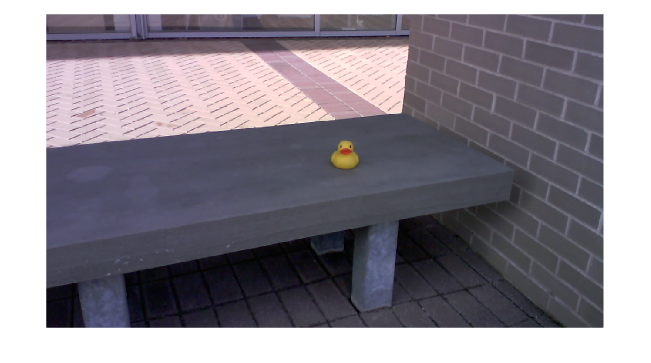


imshow(im27)

%imshow(anomalyRX(im27))

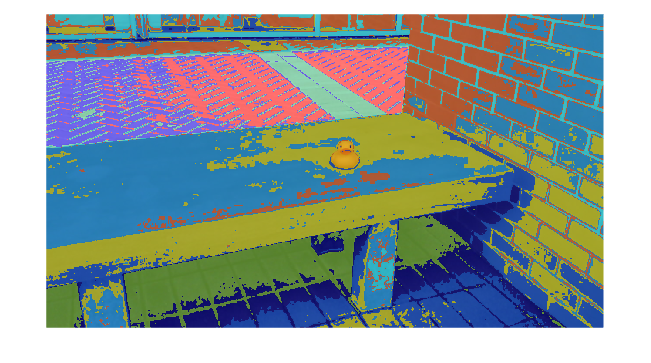

num_clusters = 11;
curr_img = im27;
curr_img_hsv = rgb2hsv(curr_img);
curr_img_hue = curr_img_hsv(:, :, 1);

[segments, ~] = imsegkmeans(curr_img,num_clusters);
curr_img_overlay = labeloverlay(curr_img, segments);
imshow(curr_img_overlay)


duck_hue = 0.09;

curr_best_region = -1;
curr_best_hue = 0;

for i=1:num_clusters
    curr_region_hue = curr_img_hue(segments == i);
    mean_hue = mean(nonzeros(curr_region_hue))
    if curr_best_region == -1
        curr_best_region = i;
        curr_best_hue = mean_hue;
    elseif abs(duck_hue - curr_best_hue) > abs(duck_hue - mean_hue)
        curr_best_region = i;
        curr_best_hue = mean_hue;
    end
end

mean_hue = 0.8656

mean_hue = 0.6766

mean_hue = 0.4070

mean_hue = 0.6618

mean_hue = 0.6671

mean_hue = 0.7537

mean_hue = 0.6690

mean_hue = 0.8080

mean_hue = 0.6834

mean_hue = 0.1185

mean_hue = 0.8080

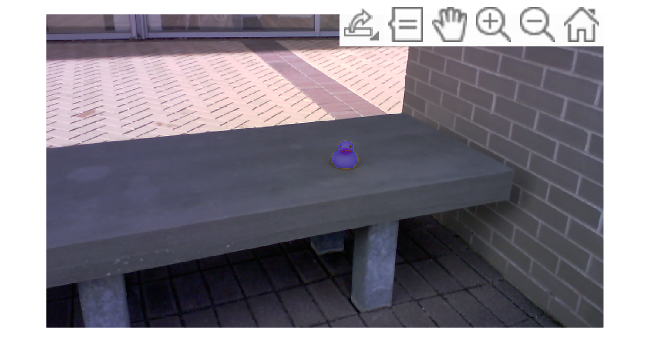


segments(segments ~= curr_best_region) = 0;
segments(segments == curr_best_region) = 2;

best_overlay = labeloverlay(curr_img, segments);
figure()
imshow(best_overlay)

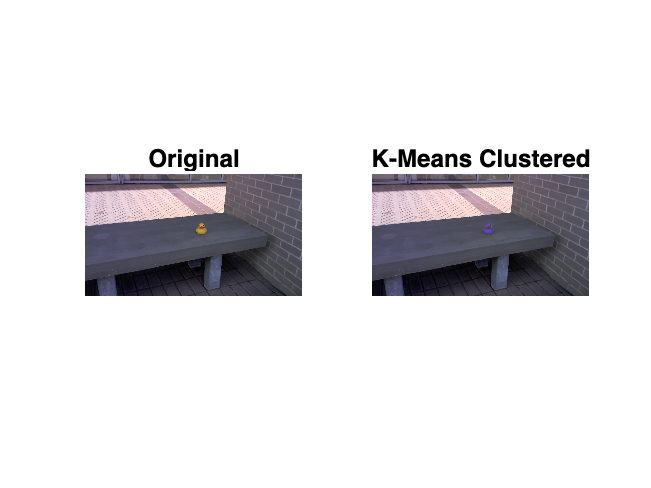


figure()
subplot(1, 2, 1)
imshow(im27)
title("Original")
subplot(1, 2, 2)
imshow(best_overlay)
title("K-Means Clustered")